Effectiveness profiling of RSQP from wind tunnel data

ismac = 0;
if ismac
    p = parselog('/Users/tomasodeponti/Desktop/19_21_53 2/22_02_10__19_21_53.data');
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw'))
else
    p = parselog('C:\Users\Tomaso\Desktop\19_21_53\19_21_53\22_02_10__19_21_53.data');
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end

ac_data = p.aircrafts.data;

Select filtering criteria

la_x = ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_x - mean(ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_x);
la_y = ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_y - mean(ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_y);
la_z = ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_z - mean(ac_data.STAB_ATTITUDE_FULL_INDI.body_accel_z);

y_x = fft(la_x);
y_y = fft(la_y);
y_z = fft(la_z);

n = length(la_x);          % number of samples
fs = get_sf(ac_data.STAB_ATTITUDE_FULL_INDI.timestamp);
f = (0:n-1)*(fs/n);     % frequency range
power_x = abs(y_x).^2/n;    % power of the DFT
power_y = abs(y_y).^2/n;
power_z = abs(y_z).^2/n;
power   = power_x + power_y + power_z;

figure(101)
subplot(4,1,1)
plot(f,power_x)
xlabel('Frequency')
ylabel('Power')
title('X')

subplot(4,1,2)
plot(f,power_y)
xlabel('Frequency')
ylabel('Power')
title('Y')

subplot(4,1,3)
plot(f,power_z)
xlabel('Frequency')
ylabel('Power')
title('Z')

subplot(4,1,4)
plot(f,power)
xlabel('Frequency')
ylabel('Power')
title('Total')

f_filter = 1.45;%3;

Prepare acceleration signal

rot_times = wing_rot_finder(ac_data);
t_acc = ac_data.STAB_ATTITUDE_FULL_INDI.timestamp;
p = ac_data.STAB_ATTITUDE_FULL_INDI.angular_rate_p;
q = ac_data.STAB_ATTITUDE_FULL_INDI.angular_rate_q;
r = ac_data.STAB_ATTITUDE_FULL_INDI.angular_rate_r;
sf_acc = get_sf(t_acc);
a_p = low_butter(diff_scaled(p,t_acc),f_filter,sf_acc,0);
a_q = low_butter(diff_scaled(q,t_acc),f_filter,sf_acc,0);
a_r = low_butter(diff_scaled(r,t_acc),f_filter,sf_acc,0);
acc = [a_p,a_q,a_r];

Prepare actuator command signal 0-9600

act_names = ["Motor Front","Motor Right","Motor Back","Motor Left","Aileron Left", "Aileron Right","Elevator","Rudder","Push Motor","Rot Mech"];
act = cellfun(@(S) sscanf(S, '%f,').', ac_data.STAB_ATTITUDE_FULL_INDI.u, 'Uniform', 0);
act = cell2mat(act);


act1 = low_butter(act(:,1),f_filter,sf_acc,0);
act2 = low_butter(act(:,2),f_filter,sf_acc,0);
act3 = low_butter(act(:,3),f_filter,sf_acc,0);
act4 = low_butter(act(:,4),f_filter,sf_acc,0);
act5 = low_butter(act(:,5),f_filter,sf_acc,0);
act6 = low_butter(act(:,6),f_filter,sf_acc,0);
act7 = low_butter(act(:,7),f_filter,sf_acc,0);
act8 = low_butter(act(:,8),f_filter,sf_acc,0);

pwm_as = [1100,1900];
pwm_mot = [1000,2000];
pprz_as = [-9600,9600];
pprz_mot = [0,9600];

rate_lim = 1230000;
fo_mot = 24.5;
fo_as  = 52.8;

m1 = pwm2pprz(pp_limiter(act1,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf_acc),pwm_mot,pprz_mot);
m2 = pwm2pprz(pp_limiter(act2,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf_acc),pwm_mot,pprz_mot);
m3 = pwm2pprz(pp_limiter(act3,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf_acc),pwm_mot,pprz_mot);
m4 = pwm2pprz(pp_limiter(act4,pwm_mot(2),pwm_mot(1),0,rate_lim/9.6, fo_mot, sf_acc),pwm_mot,pprz_mot);
as1 = pwm2pprz(pp_limiter(act5,pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf_acc),pwm_as,pprz_as);
as2 = pwm2pprz(pp_limiter(act6,pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf_acc),pwm_as,pprz_as);
as3 = pwm2pprz(pp_limiter(act7,pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf_acc),pwm_as,pprz_as);
as4 = pwm2pprz(pp_limiter(act8,pwm_as(2),pwm_as(1),0,rate_lim/9.6, fo_as, sf_acc),pwm_as,pprz_as);


act_aug = [m1,m2,m3,m4,as1,as2,as3,as4,ones(size(m1))];

Select only timestamps where doublets were performed to estimate the effectiveness of the actuators.

     1



    "Actuator"         "Roll"         "Pitch"       "Yaw"       
    "Motor Front"      "-0.041977"    "1.0627"      "0.15373"   
    "Motor Right"      "-2.305"       "-0.44711"    "-0.25052"  
    "Motor Back"       "0.017378"     "-0.50798"    "0.53667"   
    "Motor Left"       "2.1758"       "0.55787"     "-0.51823"  
    "Aileron Left"     "1.1385"       "-0.11442"    "-0.0061911"
    "Aileron Right"    "0.98094"      "-0.16655"    "0.24112"   
    "Elevator"         "0.12597"      "-0.26764"    "-0.029992" 
    "Rudder"           "0.066818"     "0.020937"    "0.20207"   



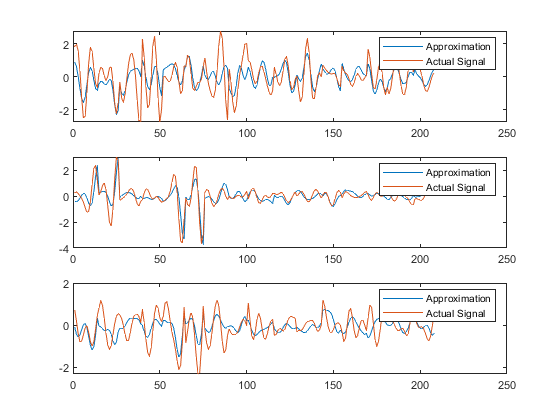

         0.837473976604166          0.50044871894594         0.542590146490815



     2



    "Actuator"         "Roll"        "Pitch"       "Yaw"     
    "Motor Front"      "-0.29369"    "0.70855"     "-0.16904"
    "Motor Right"      "-1.6564"     "-1.1935"     "-0.54022"
    "Motor Back"       "-0.18859"    "-0.21356"    "0.63814" 
    "Motor Left"       "1.6714"      "0.4831"      "-0.58352"
    "Aileron Left"     "-1.2696"     "-0.40242"    "0.22671" 
    "Aileron Right"    "0.11131"     "-0.13785"    "0.22865" 
    "Elevator"         "0.24343"     "0.24062"     "0.29285" 
    "Rudder"           "0.032334"    "0.1233"      "0.096603"



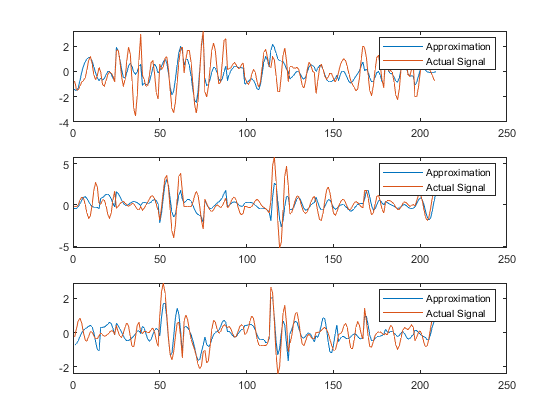

         0.896477806998451           1.0741835309855         0.518963146248436



slack_match = 0.1+0.2;%0.57;
dou_active = ac_data.DOUBLET.doublet_active;
t_d_active = ac_data.DOUBLET.timestamp(dou_active==1)+slack_match;
t_s = [];
t_e = [];
i_s = [];
i_e = [];
n = size(ac_data.DOUBLET.timestamp,1);
%check = 1;
for i=2:n
    a = dou_active(i-1);
    b = dou_active(i);
    if a==0 && b==1
        t_s = [t_s,ac_data.DOUBLET.timestamp(i)+slack_match];
        i_s = [i_s,i+round(slack_match*sf_acc,0)];
    elseif a==1 && b==0
        t_e = [t_e,ac_data.DOUBLET.timestamp(i)+slack_match];
        i_e = [i_e,i+round(slack_match*sf_acc,0)];
        %check = check+1;
    end
%     if check > 16
%         break
%     end
end

idx_save = [];
save_mat = [];
slack = 0.2;%0.2;

n_m = 16;
debug = 0;
n_wing_sp = 2;
for i=1:size(t_s,2)
    
    idx_s = t_finder(t_acc,t_s(i)-slack);
    idx_e = t_finder(t_acc,t_e(i)+slack);
    %if i <= n_m
    idx_save = [idx_save,idx_s:idx_e];
    n = fix(i/2)+mod(i,2)- 8 * fix(i/(n_m+1));
    if debug
            act_aug_d = [act_aug(idx_s:idx_e,n),act_aug(idx_s:idx_e,end)];
            acc_d = acc(idx_s:idx_e,:);
            effectiveness_mat = act_aug_d\acc_d;
            disp(act_names(n))
            disp(effectiveness_mat)

            figure(i)
            clf
            
            ax1=subplot(2,1,1);
            plot(t_acc(idx_s:idx_e),acc(idx_s:idx_e,:))
            legend("Roll","Pitch","Yaw")
            title(act_names(n))
            ax2=subplot(2,1,2);
            plot(t_acc(idx_s:idx_e),act_aug_d(:,1))
            hold on
            plot(ac_data.DOUBLET.timestamp(i_s(i):i_e(i)),ones(size(i_s(i):i_e(i))).*mean(act_aug_d(:,1)))
            
            linkaxes([ax1,ax2],'x');
            hold off
    end
    %end
    if mod(i,n_m) == 0 %perform full estimation
        idx_save = idx_save.';
        act_aug_d = act_aug(idx_save,1:end-1);
        acc_d = acc(idx_save,:);
        effectiveness_mat = act_aug_d\acc_d;
        magnifying = 1000;
        save_mat = [save_mat,effectiveness_mat];
        math_mat = effectiveness_mat;
        effectiveness_mat = effectiveness_mat * magnifying;
        effectiveness_mat = [act_names(1:8).', effectiveness_mat(1:end,:)];
        effectiveness_mat = ["Actuator","Roll","Pitch","Yaw";effectiveness_mat];
        disp(fix(i/n_m))
        disp(effectiveness_mat)
        approx = act_aug_d * math_mat;
        figure(200+fix(i/n_m))
        clf
        ax1=subplot(3,1,1);
        plot(approx(:,1))
        hold on
        plot(acc_d(:,1))
        legend("Approximation","Actual Signal")
        
        ax2=subplot(3,1,2);
        plot(approx(:,2))
        hold on
        plot(acc_d(:,2))
        legend("Approximation","Actual Signal")
        
        ax3=subplot(3,1,3);
        plot(approx(:,3))
        hold on
        plot(acc_d(:,3))
        legend("Approximation","Actual Signal")
        linkaxes([ax1,ax2,ax3],'x');
        hold off

        RMSE = sqrt(mean((acc_d - approx).^2));
        idx_save = [];
        disp(RMSE)
        
    end
end

for j =1:(size(save_mat,2)/3-1)
    k = j-1;
    delta_mat = round((save_mat(:,1+j*3:3+j*3)-save_mat(:,1+k*3:3+k*3))./save_mat(:,1+k*3:3+k*3).*100,2);
    disp("Delta Mat")
    disp(j)
    format longG
    disp(["Actuator","Roll","Pitch","Yaw";[act_names(1:8).',delta_mat]])
end

Delta Mat


     1



    "Actuator"         "Roll"        "Pitch"     "Yaw"     
    "Motor Front"      "599.65"      "-33.33"    "-209.96" 
    "Motor Right"      "-28.14"      "166.94"    "115.64"  
    "Motor Back"       "-1185.22"    "-57.96"    "18.91"   
    "Motor Left"       "-23.18"      "-13.4"     "12.6"    
    "Aileron Left"     "-211.51"     "251.69"    "-3761.95"
    "Aileron Right"    "-88.65"      "-17.23"    "-5.17"   
    "Elevator"         "93.24"       "-189.9"    "-1076.43"
    "Rudder"           "-51.61"      "488.9"     "-52.19"  



Perform estimation over multiple doublets to reduce bias error


idx_save = idx_save.';
act_aug_d = act_aug(idx_save,1:end);
acc_d = acc(idx_save,:);
effectiveness_mat = act_aug_d\acc_d;
magnifying = 1000;
save_mat = effectiveness_mat;
effectiveness_mat = effectiveness_mat * magnifying;
effectiveness_mat = [act_names(1:8).', effectiveness_mat(1:end-1,:)];
effectiveness_mat = ["Actuator","Roll","Pitch","Yaw";effectiveness_mat];

disp(effectiveness_mat)

test results 

approx = act_aug_d * save_mat;
figure(20)
clf
ax1=subplot(3,1,1);
plot(approx(:,1))
hold on
plot(acc_d(:,1))
legend("Approximation","Actual Signal")

ax2=subplot(3,1,2);
plot(approx(:,2))
hold on
plot(acc_d(:,2))
legend("Approximation","Actual Signal")

ax3=subplot(3,1,3);
plot(approx(:,3))
hold on
plot(acc_d(:,3))
legend("Approximation","Actual Signal")
% ax1=subplot(3,1,1);
% plot(t_acc(idx_save),approx(:,1))
% hold on
% plot(t_acc(idx_save),acc_d(:,1))
% legend("Approximation","Actual Signal")
% 
% ax2=subplot(3,1,2);
% plot(t_acc(idx_save),approx(:,2))
% hold on
% plot(t_acc(idx_save),acc_d(:,2))
% legend("Approximation","Actual Signal")
% 
% ax3=subplot(3,1,3);
% plot(t_acc(idx_save),approx(:,3))
% hold on
% plot(t_acc(idx_save),acc_d(:,3))
% legend("Approximation","Actual Signal")

linkaxes([ax1,ax2,ax3],'x');
RMSE = sqrt(mean((acc_d - approx).^2));